## **Testul cuadraturi gaussiene**

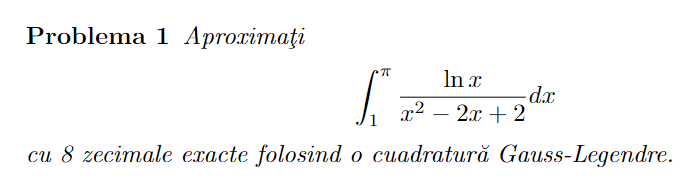

f = @(x) log(x)./(x.^2 - 2. * x + 2);

n0 = 10;
prec = 1e-8;

format long
Gauss_Legendre_ab(f, n0, 1, pi, prec)

ans =    0.584942806754295


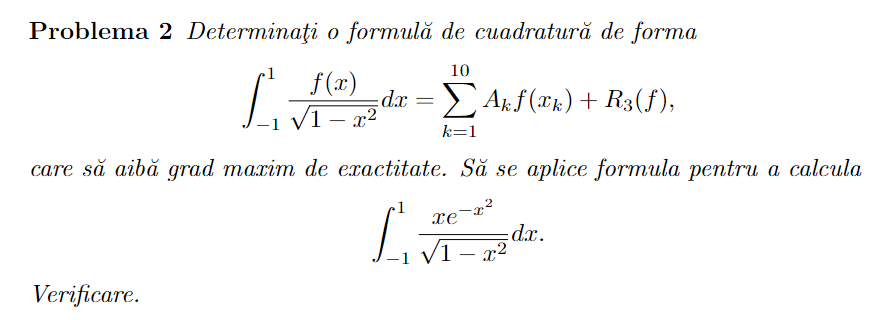

n = 10;
f = @(x) x.*exp(-x.^2);

[g_nodes, g_coeff] = Gauss_Cheb1(n);
I = vquad(g_nodes, g_coeff, f);

ff = @(x) f(x)./sqrt(1 - x.^2);
II = integral(ff, -1, 1);

diff = abs(II-I)

diff =      1.110223024625157e-16


syms t;
err = double(vpa(1/factorial(2*n)*int(chebyshevT(n,t)^2./sqrt(1-t^2),t,-1,1)))

err =      6.456471824659079e-19


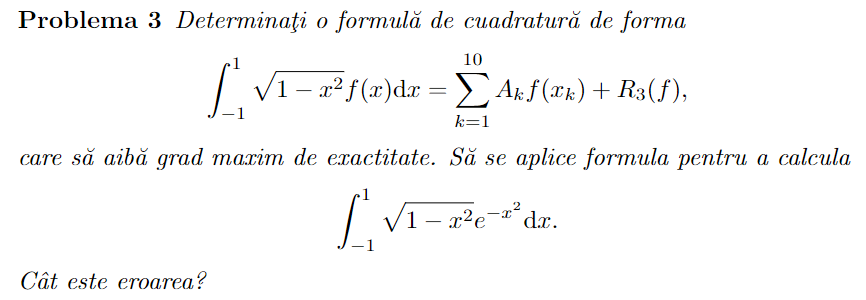

f = @(x) exp(-x.^2);
n = 10;
[g_nodes, g_coeff] = Gauss_Cheb2(n);
I = vquad(g_nodes, g_coeff, f)

I =    1.258924256551518



ff = @(x) exp(-x.^2).*sqrt(1-x.^2);
II = integral(ff, -1, 1)

II =    1.258924256551782



syms t;
err = double(vpa(1/factorial(2 * n) * int(chebyshevU(n, t)^2 * sqrt(1 - t^2), t, -1, 1)))

err =      6.456471824659079e-19


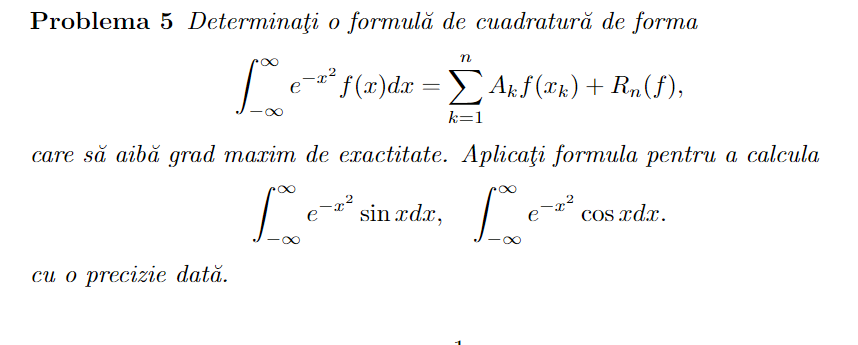

err = 1e-8;
while 1
    R=vpa(1/factorial(2*n)*int(exp(-t^2)*hermiteH(n,t)^2,t,sym(-Inf),sym(Inf)));
    if R < err
        R, n, break;
    end
    n = n + 1;
end

$$R = 0.0000000027071561636475606663458403563538$$

n =     10


[g_nodes, g_coeff] = Gauss_Hermite(n);
v1 = vquad(g_nodes, g_coeff, @sin)

v1 =     -2.165151738453552e-16


v2 = vquad(g_nodes, g_coeff, @cos)

v2 =    1.380388447043140


v11 = double(int(exp(-t^2)*sin(t),t,sym(-Inf),sym(Inf)))

v11 =      0


v22 = double(int(exp(-t^2)*cos(t),t,sym(-Inf),sym(Inf)))

v22 =    1.380388447043143


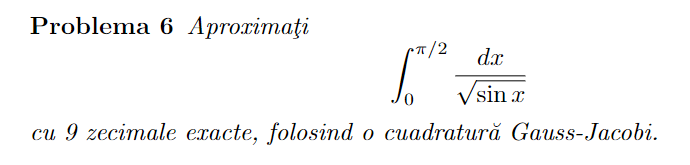

% schimbare de variabila: t = arcsin((u+1)/2)
f = @(x) sqrt(2)./sqrt(x + 3);
a = -1/2;
b = -1/2;
err = 1e-9;
n = 10;
[t, w] = Gauss_Jacobi(n, a, b);
I0 = vquad(t, w, f)

I0 =    2.622057554292118


Gauss_Jacobi_prec(f, n, a, b, I0, err)

ans =    2.622057554292118


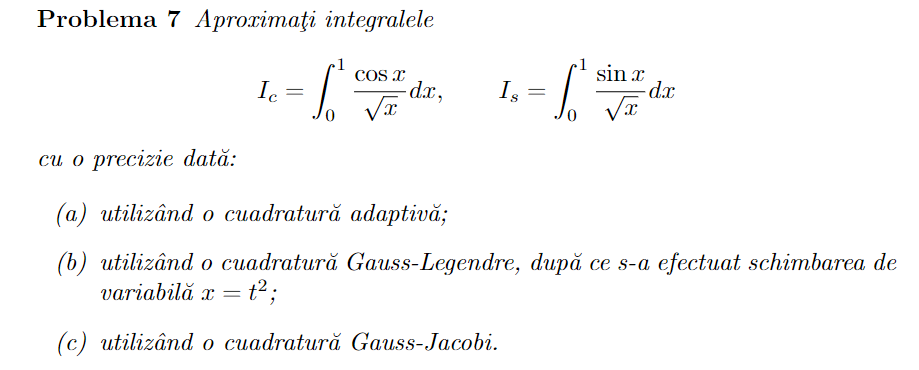

% a) cuadratura adaptiva
% schimbare de variabila: x = t ^ 2
fca = @(x) 2.*cos(x.^2); % functia corespunzatoare lui Ic
fsa = @(x) 2.*sin(x.^2); % functia corespunzatoare lui Is
disp(adquad2(fca, 0, 1));

   1.809051370874701



disp(adquad2(fsa, 0, 1));

   0.620537681663337




% b) cuadratura Gauss-Legendre
% schimbare de variabila: x = t ^ 2
fcb = @(t) cos(t.^2); % functia corespunzatoare lui Ic, b)
fsb = @(t) sin(t.^2); % functia corespunzatoare lui Is, b)
n = 10;
[g_nodes, g_coeff] = Gauss_Legendre(n);
disp(vquad(g_nodes, g_coeff, fcb));

   1.809048475801257



disp(vquad(g_nodes, g_coeff, fsb));

   0.620536603447130




% cuadratura Gauss-Jacobi 
% schimbare de variabila: x = (t+1)/2
fcc = @(x) sqrt(2)/2.*cos((x + 1)./2); % functia corespunzatoare lui Ic, c)
fsc = @(x) sqrt(2)/2.*sin((x + 1)./2); % functia corespunzatoare lui Is, c)
a = 0;
b = -1/2;
[g_nodes, g_coeff] = Gauss_Jacobi(n, a, b);
disp(vquad(g_nodes, g_coeff, fcc));

   1.809048475800544



disp(vquad(g_nodes, g_coeff, fsc));

   0.620536603446763



function I = Gauss_Jacobi_prec(f, n, a, b, I0, err)     % pb 6
while 1
    n = n + 1;
    [t, w] = Gauss_Jacobi(n, a, b);
    I = vquad(t, w, f);
    if abs(I0 - I) < err || n > 1000
        I = I0;
        break;
    end
    I0 = I;
end
end